# Example 15.2

syms V_U V_L t T_A T_B s
u0(t) = heaviside(t)

$$u0(t) = \mathrm{heaviside}\left(t\right)$$

x(t) = V_L*(u0(t)-u0(t-T_A))+V_U*(u0(t-T_A)-u0(t-(T_A + T_B)))

$$x(t) = V_{L}\,\left(\mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-T_{A}\right)\right)-V_{U}\,\left(\mathrm{heaviside}\left(t-T_{B}-T_{A}\right)-\mathrm{heaviside}\left(t-T_{A}\right)\right)$$


RC = 1

RC = 1

x(t) = subs(x(t),[V_L,V_U,T_A,T_B],[-5,5,RC,RC/2])

$$x(t) = 10\,\mathrm{heaviside}\left(t-1\right)-5\,\mathrm{heaviside}\left(t-\frac{3}{2}\right)-5\,\mathrm{heaviside}\left(t\right)$$

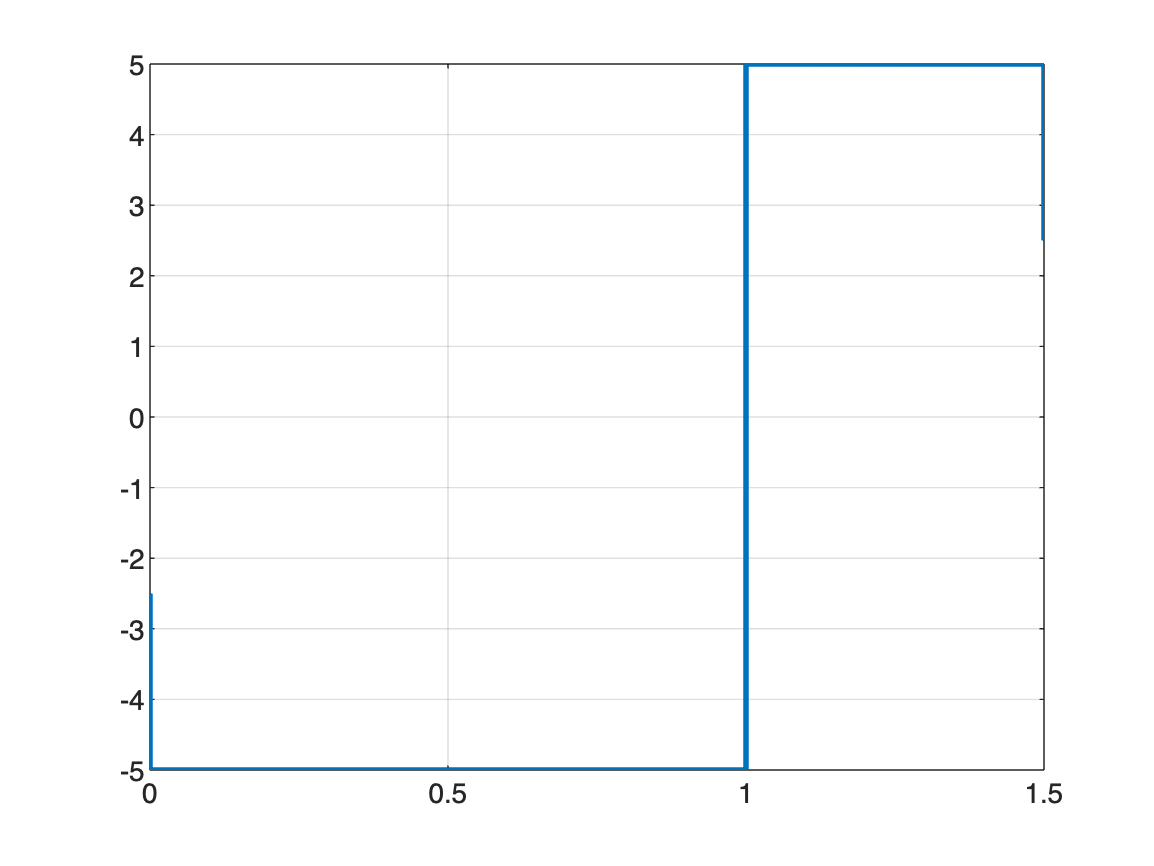

fplot(x(t),[0,3*RC/2],'LineWidth',2),grid


X(s) = laplace(x(t))

$$X(s) = \frac{10\,{\mathrm{e}}^{-s}}{s}-\frac{5\,{\mathrm{e}}^{-\frac{3\,s}{2}}}{s}-\frac{5}{s}$$

System

syms R C
H = s/(s + 1/(R*C))

$$H = \frac{s}{s+\frac{1}{C\,R}}$$

h(t) = ilaplace(H)

$$h(t) = \delta (t)-\frac{{\mathrm{e}}^{-\frac{t}{C\,R}}}{C\,R}$$

Xu = 1/s; 
Y = H*Xu;
y = ilaplace(Y)

$$y = {\mathrm{e}}^{-\frac{t}{C\,R}}$$

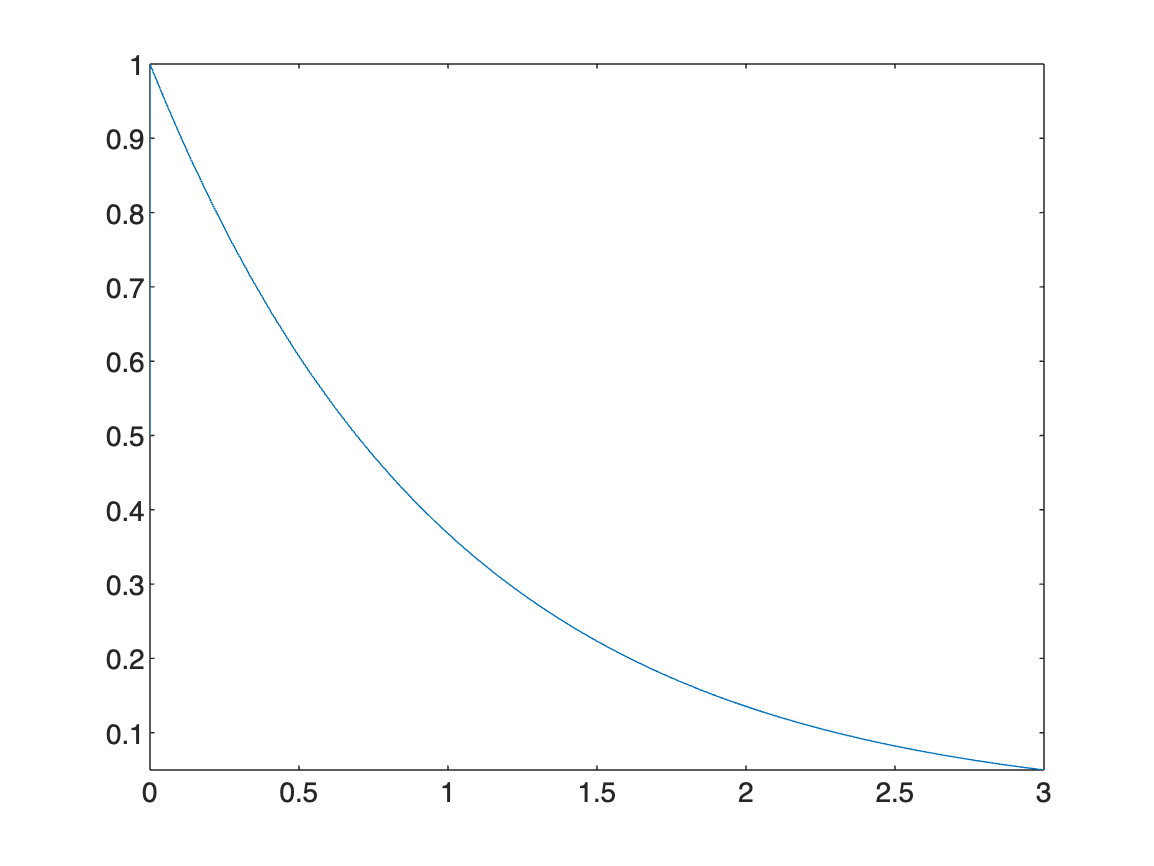

fplot(subs(y*u0(t),R*C,RC),[0,3*RC])

Y(s)=H*X(s)

$$Y(s) = -\frac{s\,\left(\frac{5\,{\mathrm{e}}^{-\frac{3\,s}{2}}}{s}-\frac{10\,{\mathrm{e}}^{-s}}{s}+\frac{5}{s}\right)}{s+\frac{1}{C\,R}}$$

y(t) = ilaplace(Y(s))*u0(t)

$$y(t) = -\mathrm{heaviside}\left(t\right)\,\left(5\,{\mathrm{e}}^{-\frac{t}{C\,R}}-10\,\mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{-\frac{t-1}{C\,R}}+5\,\mathrm{heaviside}\left(t-\frac{3}{2}\right)\,{\mathrm{e}}^{-\frac{t-\frac{3}{2}}{C\,R}}\right)$$

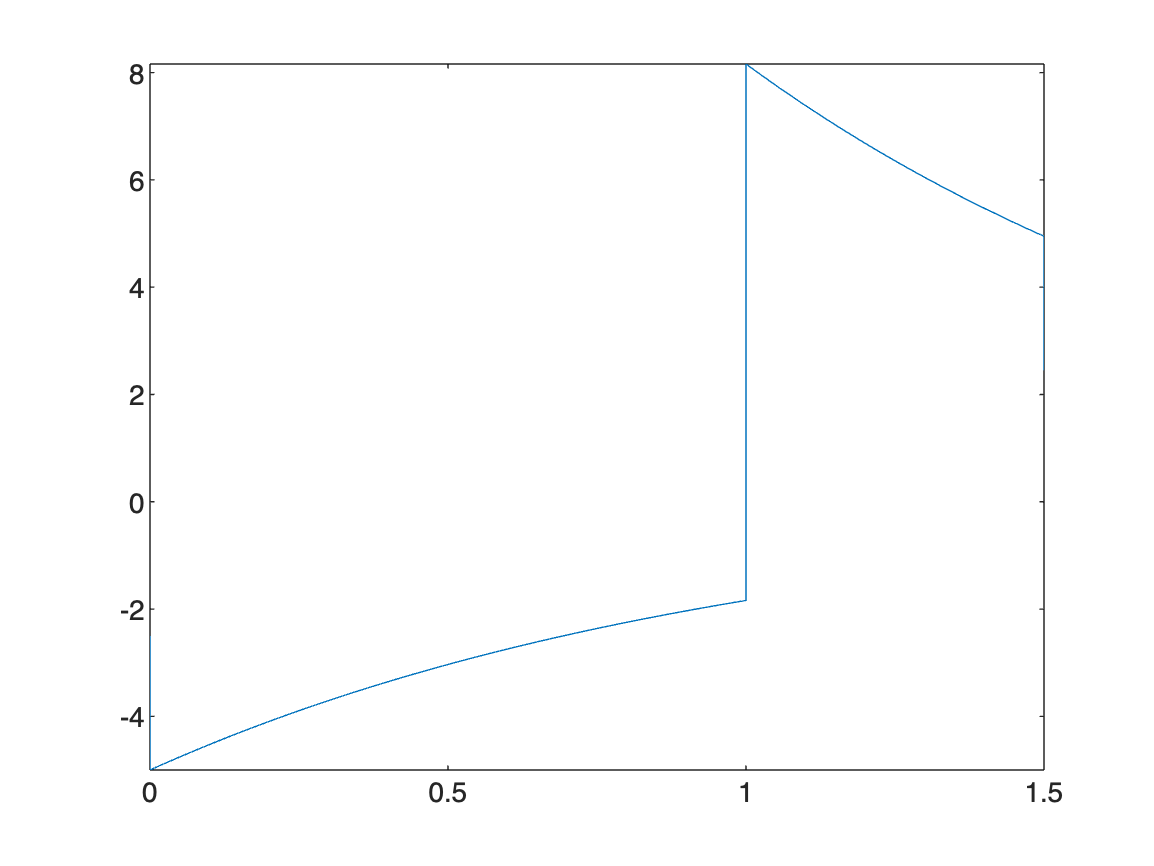

fplot(subs(y(t),R*C,RC),[0,3*RC/2])

Try extending this to a periodic functio

y(t) = y(t) + y(t - 3*RC/2) + y(t - 6*RC/2) + y(t - 9*RC/2) + y(t - 12*RC/2) + y(t - 15*RC/2)

$$y(t) = -\mathrm{heaviside}\left(t-\frac{3}{2}\right)\,\left(5\,{\mathrm{e}}^{-\frac{t-\frac{3}{2}}{C\,R}}+5\,\mathrm{heaviside}\left(t-3\right)\,{\mathrm{e}}^{-\frac{t-3}{C\,R}}-10\,\mathrm{heaviside}\left(t-\frac{5}{2}\right)\,{\mathrm{e}}^{-\frac{t-\frac{5}{2}}{C\,R}}\right)-\mathrm{heaviside}\left(t-3\right)\,\left(5\,{\mathrm{e}}^{-\frac{t-3}{C\,R}}-10\,\mathrm{heaviside}\left(t-4\right)\,{\mathrm{e}}^{-\frac{t-4}{C\,R}}+5\,\mathrm{heaviside}\left(t-\frac{9}{2}\right)\,{\mathrm{e}}^{-\frac{t-\frac{9}{2}}{C\,R}}\right)-\mathrm{heaviside}\left(t-6\right)\,\left(5\,{\mathrm{e}}^{-\frac{t-6}{C\,R}}-10\,\mathrm{heaviside}\left(t-7\right)\,{\mathrm{e}}^{-\frac{t-7}{C\,R}}+5\,\mathrm{heaviside}\left(t-\frac{15}{2}\right)\,{\mathrm{e}}^{-\frac{t-\frac{15}{2}}{C\,R}}\right)-\mathrm{heaviside}\left(t-\frac{9}{2}\right)\,\left(5\,{\mathrm{e}}^{-\frac{t-\frac{9}{2}}{C\,R}}+5\,\mathrm{heaviside}\left(t-6\right)\,{\mathrm{e}}^{-\frac{t-6}{C\,R}}-10\,\mathrm{heaviside}\left(t-\frac{11}{2}\right)\,{\mathrm{e}}^{-\frac{t-\frac{11}{2}}{C\,R}}\right)-\mathrm{heaviside}\left(t-\frac{15}{2}\right)\,\left(5\,{\mathrm{e}}^{-\frac{t-\frac{15}{2}}{C\,R}}+5\,\mathrm{heaviside}\left(t-9\right)\,{\mathrm{e}}^{-\frac{t-9}{C\,R}}-10\,\mathrm{heaviside}\left(t-\frac{17}{2}\right)\,{\mathrm{e}}^{-\frac{t-\frac{17}{2}}{C\,R}}\right)-\mathrm{heaviside}\left(t\right)\,\left(5\,{\mathrm{e}}^{-\frac{t}{C\,R}}-10\,\mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{-\frac{t-1}{C\,R}}+5\,\mathrm{heaviside}\left(t-\frac{3}{2}\right)\,{\mathrm{e}}^{-\frac{t-\frac{3}{2}}{C\,R}}\right)$$

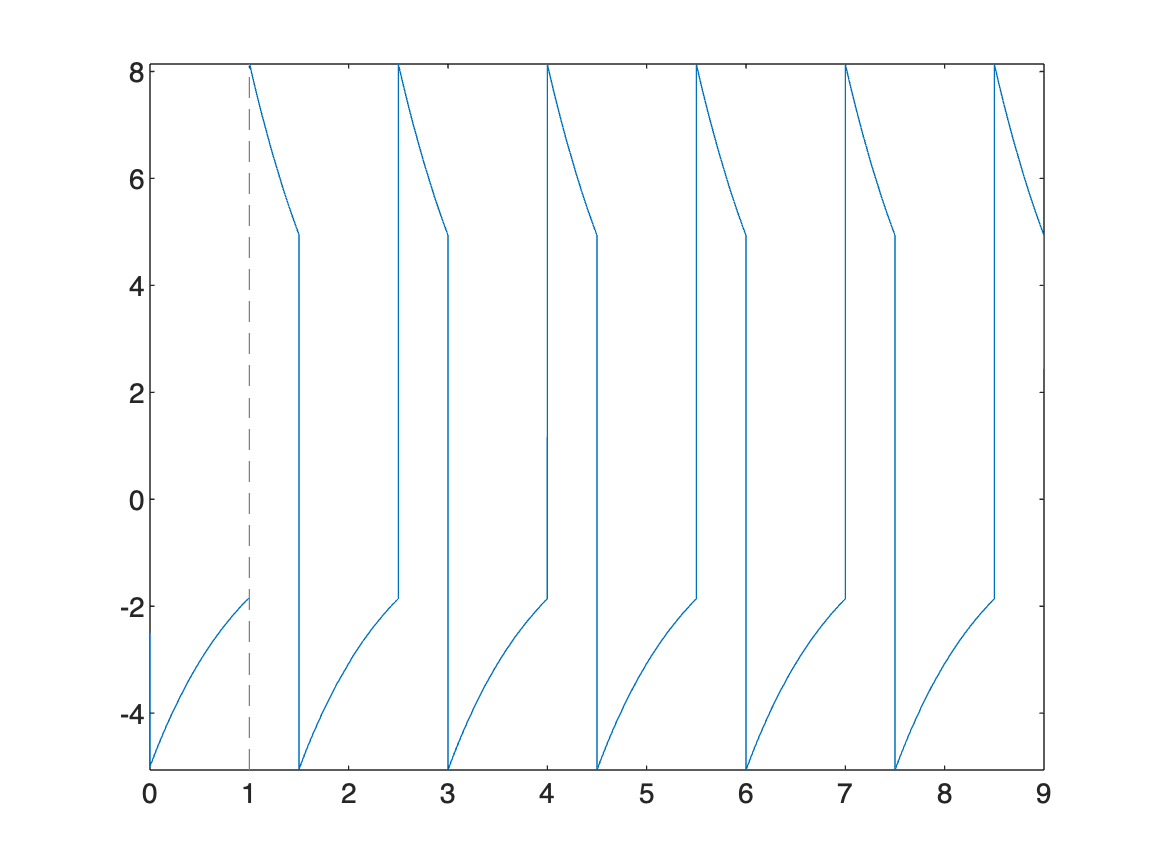

fplot(subs(y(t),R*C,RC),[0,18*RC/2])

I2 = 1/3*(s^2 + 8*s + 18)

$$I2 = \frac{s^{2}}{3}+\frac{8\,s}{3}+6$$

i2 = ilaplace(I2)

$$i2 = 6\,\delta (t)+\frac{8\,\delta^{\prime }(t)}{3}+\frac{\delta^{\prime \prime }(t)}{3}$$